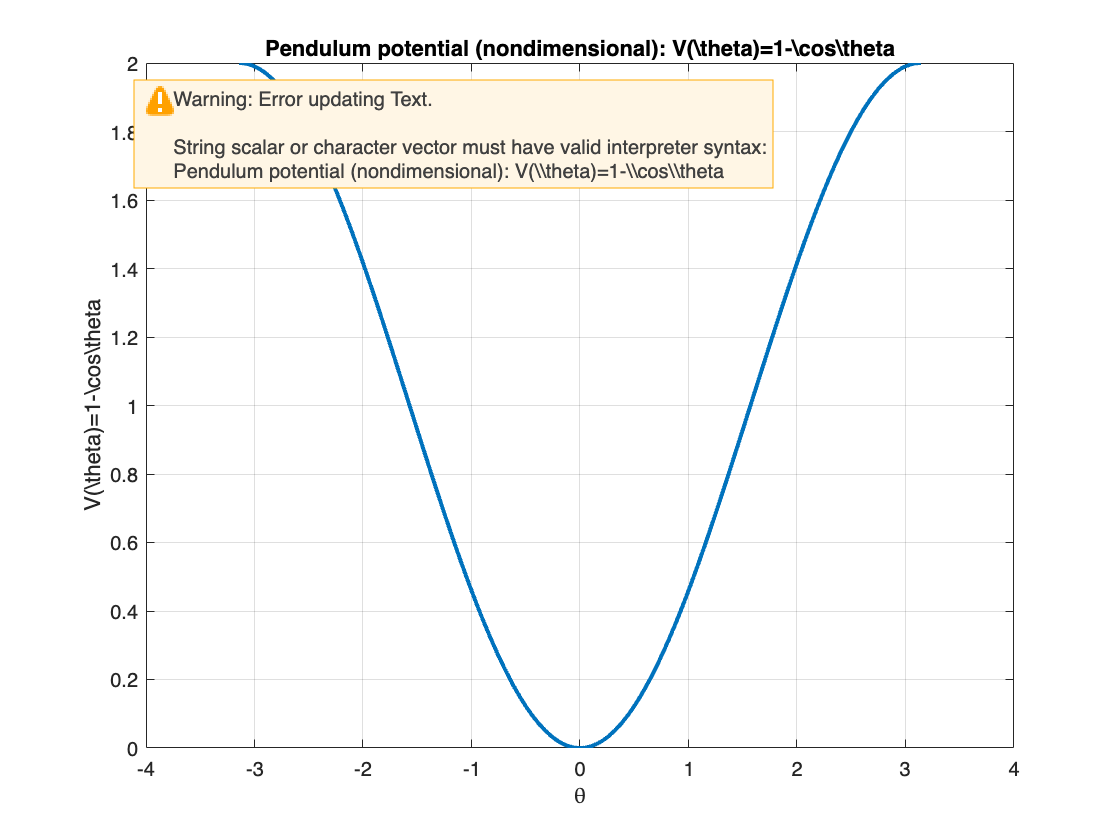

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% ex5_pendulum_conservative.m
%
% Conservative pendulum:
%   theta'' + (g/L) sin(theta) = 0
%
% We'll use nondimensionalized form (set g/L = 1):
%   theta' = omega
%   omega' = -sin(theta)
%
% Potential for the nondimensional system:
%   V(theta) = 1 - cos(theta)
% Energy:
%   E = (1/2) omega^2 + (1 - cos(theta))  (constant for conservative system)
%
% Goals:
%   - plot potential V(theta)
%   - phase portrait (theta,omega): vector field + nullclines + trajectories
%   - local linearization at equilibria (theta = k*pi, omega=0)
%   - show separatrix (E=2) dividing libration vs rotation
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

clear; close all; clc;

f = @(t,z) [ z(2);
            -sin(z(1)) ];

V = @(th) 1 - cos(th);

% Plot potential over one period
figure('Color','w','Name','Example 5: Pendulum potential');
th = linspace(-pi,pi,800);
plot(th, V(th),'LineWidth',2); grid on; box on;
xlabel('\theta'); ylabel('V(\theta)=1-\cos\theta');
title('Pendulum potential (nondimensional): V(\theta)=1-\cos\theta');


%% Phase portrait window
thlim = [-2*pi 2*pi];
omlim = [-3 3];

[thg,omg] = meshgrid(linspace(thlim(1),thlim(2),33), linspace(omlim(1),omlim(2),33));
ug = omg;
vg = -sin(thg);

figure('Color','w','Name','Example 5: Pendulum phase portrait');
hold on; box on; grid on;
quiver(thg,omg,ug,vg,'AutoScale','on');
xlabel('\theta'); ylabel('\omega');
title('\theta''=\omega, \ \omega''=-\sin\theta  (phase portrait)');

% Nullclines:
% theta' = 0 -> omega=0
% omega' = 0 -> sin(theta)=0 -> theta = k*pi
yline(0,'k--','LineWidth',1.4);
xline(-pi,'k-.','LineWidth',1.2);
xline(0,'k-.','LineWidth',1.2);
xline(pi,'k-.','LineWidth',1.2);

% Equilibria in this window: (theta,omega) = (k*pi,0)
eq = [-pi 0; 0 0; pi 0];
plot(eq(:,1),eq(:,2),'ro','MarkerFaceColor','r','MarkerSize',6);

% Local linearization at theta=0:
% J = [0 1; -cos(theta*) 0]
% at (0,0): eigenvalues ± i -> center (small oscillations)
% at (pi,0): cos(pi)=-1 -> eigenvalues ± 1 -> saddle (separatrix)
for k=1:size(eq,1)
    th0 = eq(k,1);
    J = [0 1; -cos(th0) 0];
    lam = eig(J);
    fprintf('(theta*,omega*)=(%.2f,0): eig = (%.3f, %.3f)\n', th0, lam(1), lam(2));
end

(theta*,omega*)=(-3.14,0): eig = (-1.000, 1.000)
(theta*,omega*)=(0.00,0): eig = (0.000, 0.000)
(theta*,omega*)=(3.14,0): eig = (-1.000, 1.000)


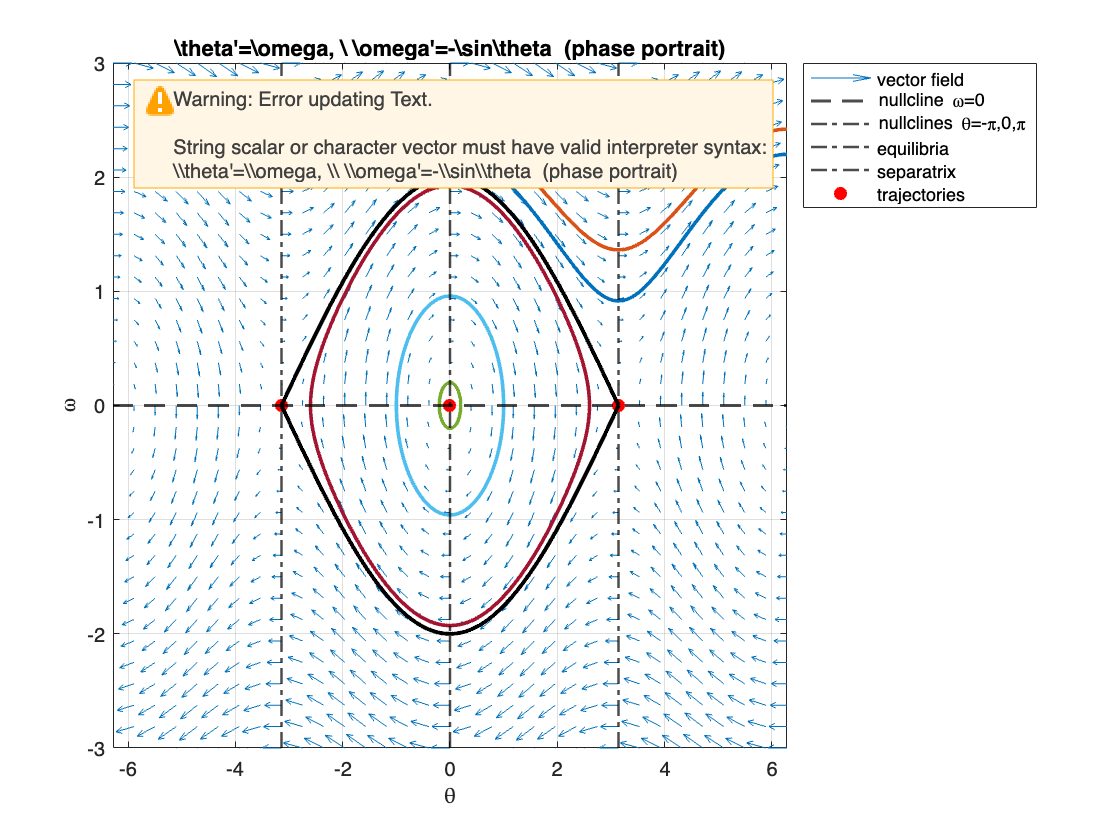


% Separatrix at energy E=2 (top of potential at theta=pi has V=2):
% E= (1/2)omega^2 + (1-cos theta) = 2
% => omega^2 = 2(2 - (1-cos theta)) = 2(1+cos theta) = 4 cos^2(theta/2)
% => omega = ±2 cos(theta/2)
th_sep = linspace(-pi,pi,800);
om_sep = 2*cos(th_sep/2);
plot(th_sep,  om_sep,'k','LineWidth',2);
plot(th_sep, -om_sep,'k','LineWidth',2);
text(-2.9,2.6,'separatrix (E=2)','FontSize',10);

% Trajectories: libration (inside), near separatrix, and rotation (outside)
tspan = [0 25];
ICs = [ 0.2  0.0;     % small oscillation
        1.0  0.0;     % larger oscillation
        2.6  0.0;     % near separatrix
        0.0  2.2;     % rotation
        -1.5  2.0 ];  % rotation

opts = odeset('RelTol',1e-9,'AbsTol',1e-11);

for k=1:size(ICs,1)
    z0 = ICs(k,:)';
    [t,z] = ode45(f,tspan,z0,opts);
    % Wrap theta into [-pi,pi] for plotting (so portrait stays in one window)
    th_wrap = z(:,1); %wrapToPi_local(z(:,1));
    plot(th_wrap, z(:,2),'LineWidth',1.8);
end

xlim(thlim); ylim(omlim);
legend({'vector field','nullcline \omega=0','nullclines \theta=-\pi,0,\pi','equilibria',...
        'separatrix','trajectories'}, 'Location','bestoutside');